clc
clear all
b = 120; %in
c = 48;
S = c*b;
q =         [10.0    11.0    11.4    11.8    12.0    12.2   12.4    12.6    12.8    13.0    13.2    13.4    13.6     13.8     14.0    14.2    14.4      14.6     14.8    15.0]

q =    10.0000   11.0000   11.4000   11.8000   12.0000   12.2000   12.4000   12.6000   12.8000   13.0000   13.2000   13.4000   13.6000   13.8000   14.0000   14.2000   14.4000   14.6000   14.8000   15.0000


Cl_rigid =  [0.1688  0.1688  0.1688  0.1688  0.1688  0.1688 0.1688  0.1688  0.1688  0.1688  0.1688  0.1688  0.1688   0.1688   0.1688  0.1688  0.1688    0.1688   0.1688  0.1688 ]

Cl_rigid =     0.1688    0.1688    0.1688    0.1688    0.1688    0.1688    0.1688    0.1688    0.1688    0.1688    0.1688    0.1688    0.1688    0.1688    0.1688    0.1688    0.1688    0.1688    0.1688    0.1688


Cl_flex =   [0.5176  0.6971  0.8136  0.9805  1.0943  1.2395 1.4312  1.6960  2.0856  2.7154  3.9062  7.0108  35.5105 -11.4362 -4.8974 -3.1046 -2.266    -1.7810  -1.4641 -1.2411 ]

Cl_flex =     0.5176    0.6971    0.8136    0.9805    1.0943    1.2395    1.4312    1.6960    2.0856    2.7154    3.9062    7.0108   35.5105  -11.4362   -4.8974   -3.1046   -2.2660   -1.7810   -1.4641   -1.2411


r = (q.*S.*Cl_flex)./(q.*S.*Cl_rigid)

r =     3.0664    4.1297    4.8199    5.8086    6.4828    7.3430    8.4787   10.0474   12.3555   16.0865   23.1410   41.5332  210.3703  -67.7500  -29.0130  -18.3922  -13.4242  -10.5509   -8.6736   -7.3525


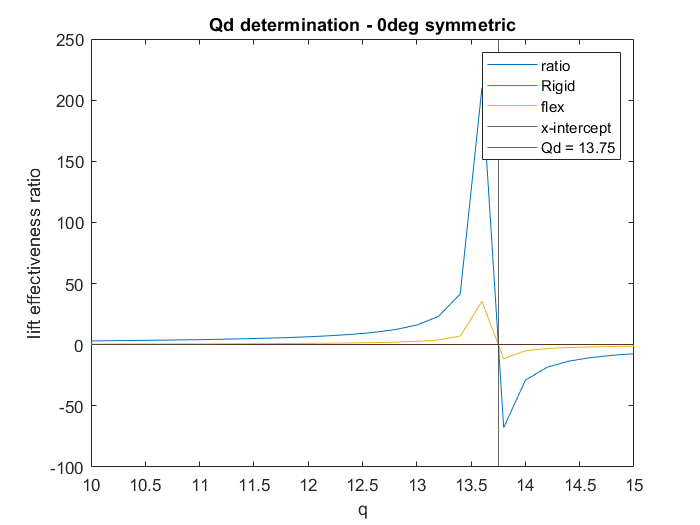

figure(1)
plot(q,r,'DisplayName','ratio')
hold on
plot(q,Cl_rigid,"DisplayName",'Rigid')
plot(q,Cl_flex,"DisplayName",'flex')
legend
title('Qd determination - 0deg symmetric')
xlabel('q')
ylabel('lift effectiveness ratio')
hold off
yline(0,'DisplayName','x-intercept') 
xline(13.75,'DisplayName','Qd = 13.75')